Spline


x=[1,2,4]

x =      1     2     4


y=[2,7,21]

y =      2     7    21



diagsupinf =

  1×0 empty double row vector



A = 6

g = 2

g =      0     2     0


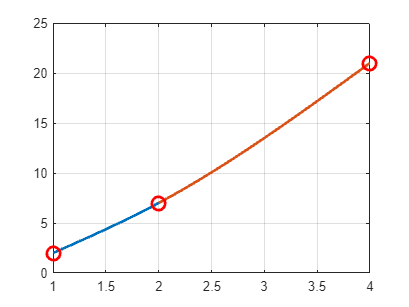

s =     0.3333         0    4.6667    2.0000
   -0.1667    1.0000    5.6667    7.0000


s = splinenatural(x,y)

function S = splinenatural(X,Y)
    N=length(X)-1; H=diff(X); E=diff(Y)./H;
    diagprinc=2*(H(1:N-1)+H(2:N)); diagsupinf=H(2:N-1)
    g0=0; gn=0;
    A=diag(diagprinc)+diag(diagsupinf,1)+diag(diagsupinf,-1)
    b=6*diff(E'); 
    g=A\b
    g=[g0 g' gn]
    figure(7); clf;
    for i=1:N
        S(i,1)=(g(i+1)-g(i))/(6*H(i));
        S(i,2)=g(i)/2;
        S(i,3)= E(i)-H(i)*(g(i+1)+2*g(i))/6;
        S(i,4)=Y(i);
        xx=linspace(X(i),X(i+1),100);
        yy=S(i,1)*(xx-X(i)).^3+S(i,2)*(xx-X(i)).^2+S(i,3)*(xx-X(i))+S(i,4);
        plot(xx,yy,'LineWidth',2), hold on
    end
    plot(X,Y,'or','MarkerSize',10,'LineWidth',2);
    grid on, hold off
end